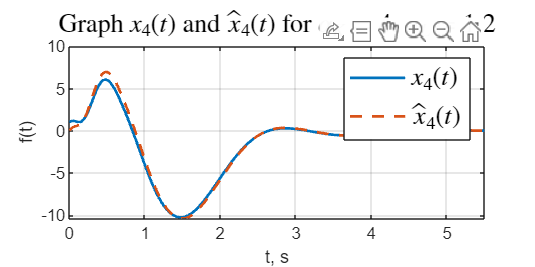

open_system('task_2_sim');
set_param('task_2_sim/x', 'VariableName', 'x')
set_param('task_2_sim/x_', 'VariableName', 'x_')
set_param('task_2_sim/u', 'VariableName', 'u')
%set_param('task_2_sim/u1', 'VariableName', 'u1')
%set_param('task_2_sim/u2', 'VariableName', 'u2')
set_param('task_2_sim/e', 'VariableName', 'e')

% k(1.2), l(4)
%K = [-11.3880 4.2120 10.7640 3.5880];
%L = [-3.9257 2.3376; -7.0845 -3.9522; 7.0101 -0.3855; -4.0001 -2.0001];
out = sim('task_2_sim');

figure('Position', [100 100 800 400])
plot(out.x.Time, out.x.Data(:,4),'-', 'LineWidth',1.5)
hold on
plot(out.x_.Time, out.x_.Data(:,4),'--', 'LineWidth',1.5)

grid()
title('Graph $x_4(t)$ and $\hat{x}_4(t)$ for $\alpha_K = 4$, $\alpha_L =1.2$','Interpreter','latex',  'FontSize', 14)
legend('$x_4(t)$', '$\hat{x}_4(t)$', 'Interpreter','latex',  'FontSize', 14)
ylabel('f(t)')
xlabel('t, s')
xlim([0 5.5])
hold off

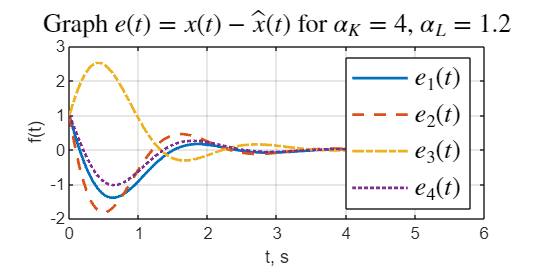


plot(out.e.Time, out.e.Data(:,1), '-', 'LineWidth',1.5)
hold on
plot(out.e.Time, out.e.Data(:,2), '--', 'LineWidth',1.5)
plot(out.e.Time, out.e.Data(:,3), '-.', 'LineWidth',1.5)
plot(out.e.Time, out.e.Data(:,4), ':', 'LineWidth',1.5)
grid()
title('Graph $e(t) = x(t) - \hat{x}(t)$ for $\alpha_K = 4$, $\alpha_L =1.2$','Interpreter','latex',  'FontSize', 14)
legend('$e_1(t)$', '$e_2(t)$','$e_3(t)$', '$e_4(t)$', 'Interpreter','latex',  'FontSize', 14)
ylabel('f(t)')
xlabel('t, s')
%xlim([0 2.2])
hold off


%plot(out.u, '-', 'LineWidth',1.5)
%hold on
% k(4), l(4)
%K = [-43.0003 23.0002 37.0002 17.0001];
%L = [-3.9257 2.3376; -7.0845 -3.9522; 7.0101 -0.3855; -4.0001 -2.0001];
%out = sim('task_2_sim');
%plot(out.u, '--', 'LineWidth',1.5)
% k(4), l(1.2)
%K = [-43.0003 23.0002 37.0002 17.0001];
%L = [-2.5640 1.4086; -3.1725 -1.7716; 3.1367 -0.9369; -2.6002 -1.3001];
%out = sim('task_2_sim');
%plot(out.u, 'k:', 'LineWidth',1.5)
%grid()
%title('Graph $u(t)$','Interpreter','latex',  'FontSize', 14)
%legend('$u(t)$: $\alpha_K = 1.2$, $\alpha_L = 4$', '$u(t)$: $\alpha_K = 4$, $\alpha_L = 4$', '$u(t)$: $\alpha_K = 4$, $\alpha_L = 1.2$', 'Interpreter','latex',  'FontSize', 14)
%ylabel('f(t)')
%xlabel('t, s')
%xlim([0 5])
%hold off




%plot(out.u, 'LineWidth', 1.5)
%hold on
%plot(out.u1, 'LineWidth', 1.5)

%grid("on")
%title('Graph $u(t)$ for $\alpha_{max} = 3$', 'Interpreter','latex',  'FontSize', 14)
%legend('$u(t)$: $K_3$', '$u(t)$: $K_4$','Interpreter','latex',  'FontSize', 14)
%ylabel('f(t)')
%xlabel('t, s')
%xlim([0 5.5])
%hold off



